# k-space analysis of PEC waveguide

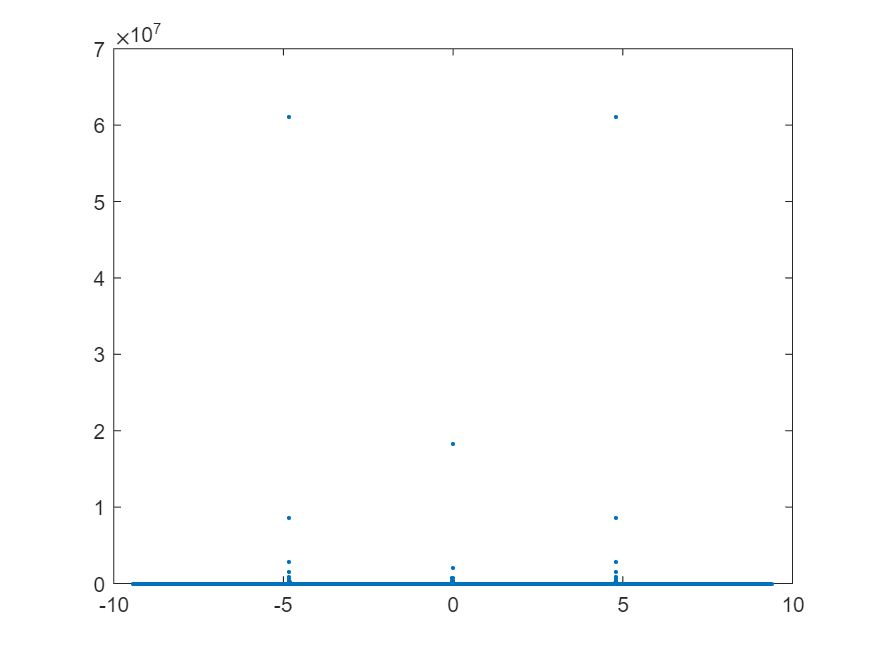

theta_in = 10*pi/180;       % rad
theta_out= 70*pi/180;       % rad

lambda = 1;                 % lambda
Lambda = lambda/abs(sin(theta_in)-sin(theta_out));  % lambda

eta = 1;                    % eta
k = 2*pi/lambda;              % 1/lambda
E0 = 1;                     % E0

NumLayers = 2;

phi0 = -k*Lambda*sin(theta_in);  %rad

reff = 6.35e-4;         % lambda for f = 10 GHz
MaxSizeLayer=lambda;

optimTimes = 500;
Norder=100;

Hs = [-0.5 ;-0.25]*lambda;
Ds = [0 ;0]*lambda;
H = 2*lambda;
Zs = [-1j ; -3j]* eta;

resultion = 10000;
ky = linspace(-1.5,1.5,resultion)*k;

detA = zeros(1,resultion);
for index = 1:resultion
    detA(index) = detCurrentMatrixKyH(k,ky(index),reff,Lambda,eta,Norder,Hs,Ds,Zs,H); 
end

figure;
grid on;
plot(ky,abs(detA)-1,'.');

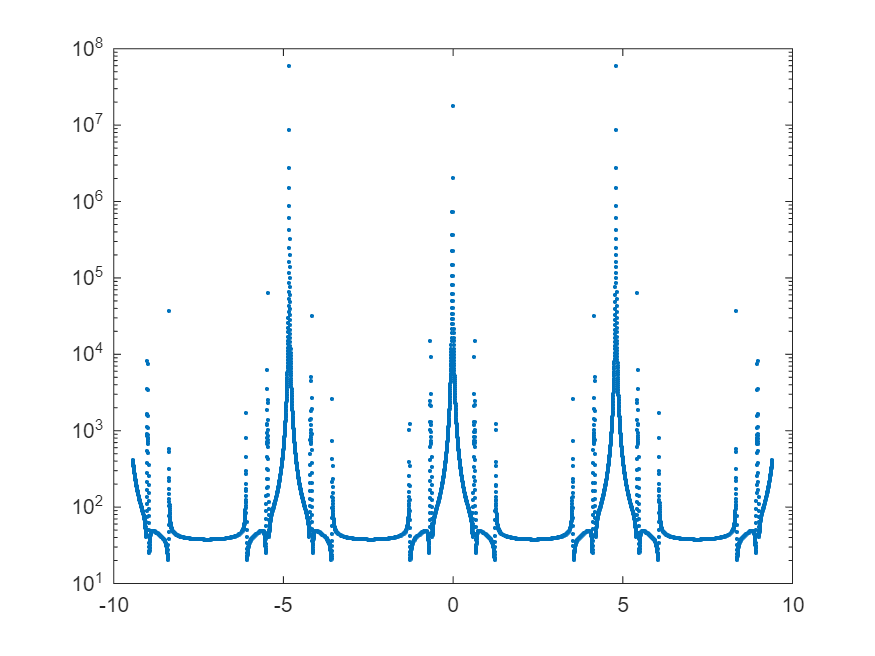


figure;
grid on;
semilogy(ky,abs(detA)-1,'.');

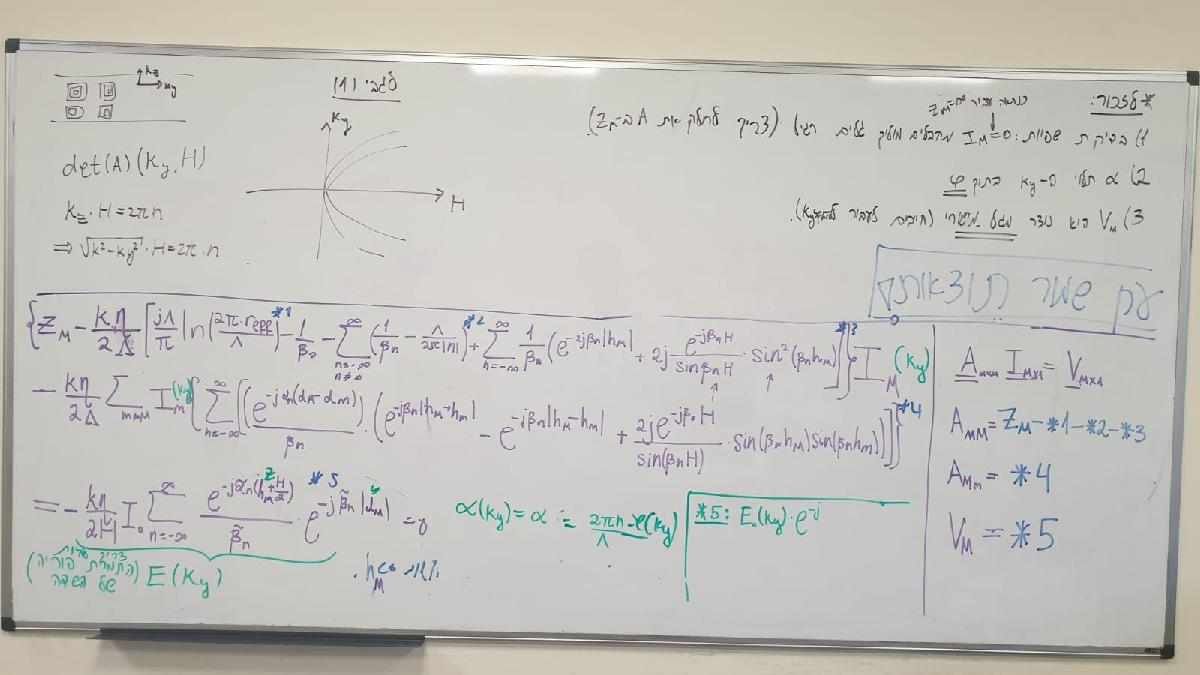

function [detMatrix] = detCurrentMatrixKyH(k,ky,reff,Lambda,eta,Norder,Hs,Ds,Zs,H)
    NumLayers = length(Hs);
    Matrix = zeros(NumLayers,NumLayers);
    phi = -ky*Lambda;
    for Mindex = 1:NumLayers
        for mindex = 1:NumLayers
            if (Mindex == mindex)
                Matrix(Mindex,mindex) = 1-k*eta/(2*Lambda*Zs(Mindex))*sumElemnts123(k,phi,Norder,reff,Lambda,Hs,H,Mindex);
            else
                Matrix(Mindex,mindex) = -k*eta/(2*Lambda*Zs(Mindex))*sumElemnts4(k,Lambda,phi,Norder,Hs,Ds,H,Mindex,mindex);
            end 
        end
    end
    detMatrix = det(Matrix);
end


function sumValue = sumElemnts123(k,phi,Norder,reff,Lambda,Hs,H,Mindex)
    nVec=(-Norder:Norder);
    nNoZero=[(-Norder:-1) (1:Norder)];
    [~,Betas] = calcAlphasBetas(k,Lambda,phi,nVec);
    [~,BetasNoZero] = calcAlphasBetas(k,Lambda,phi,nNoZero);
    element1 = 1j*Lambda/pi*log(2*pi*reff/Lambda) - 1/Betas(Norder+1);
    element2 = -sum( 1./BetasNoZero - Lambda/2/pi./abs(nNoZero),"all");
    element3 = sum(1./Betas.*(exp(-2j*Betas*abs(Hs(Mindex))) + ...
        2j*exp(-1j*Betas*H)./sin(Betas*H).*(sin(Betas*Hs(Mindex))).^2),"all");
    sumValue = element1+element2+element3;
end

function element4 = sumElemnts4(k,Lambda,phi,Norder,Hs,Ds,H,Mindex,mindex)
    nVec=(-Norder:Norder);
    [Alphas,Betas] = calcAlphasBetas(k,Lambda,phi,nVec);
    element4 = sum(exp(-1j*Alphas*(Ds(Mindex)-Ds(mindex)))./Betas.*...
        (exp(-1j*Betas*abs(Hs(Mindex)+Hs(mindex)))-exp(-1j*Betas*abs(Hs(Mindex)-Hs(mindex)))...
        +2j*exp(-1j*Betas*H)./sin(Betas*H).*sin(Betas.*Hs(Mindex)).*sin(Betas*Hs(mindex))),"all");
end

function [Alphas,Betas] = calcAlphasBetas(k,Lambda,phi,IndexVector)
    Alphas = (2*pi*IndexVector-phi)/Lambda;
    Betas  = conj(sqrt(k^2-Alphas.^2));
end